# 1.1

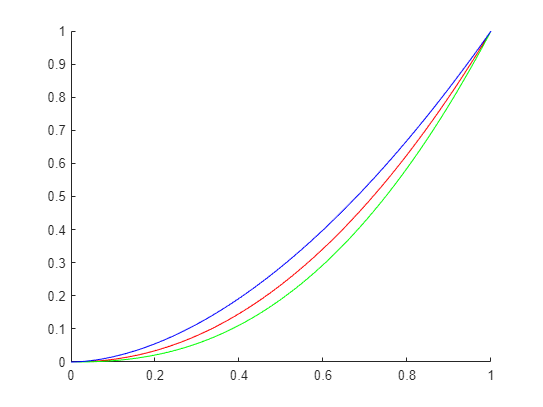

n = length(TRCr);
x = linspace(0,1,n);
hold on
plot(x,TRCr, 'r')
plot(x,TRCg, 'g')
plot(x,TRCb, 'b')

# 1.2

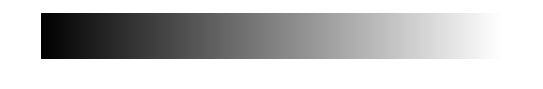

imshow(Ramp_linear)

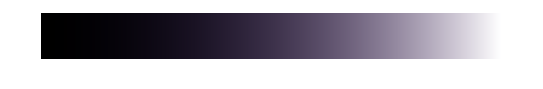

imshow(Ramp_display)

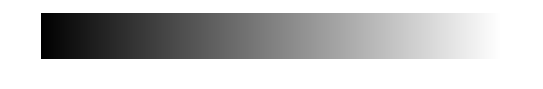


res = linearization(Ramp_display, TRCr, TRCg, TRCb);
imshow(res)

# 1.3

d = gammaCorrection(Ramp_display, [2.1, 2.4, 1.8]);

dmax = dmax(:,:,1) =

     1


dmax(:,:,2) =

     1


dmax(:,:,3) =

     1


imshow(d)

# 2.1

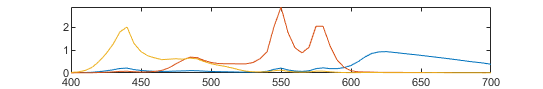

n = length(DLP);
x = linspace(400,700,n);
plot(x,DLP)

# 2.2

S = DLP*RAW_C1_CIED65

S =     0.0172    0.0077    0.0037    0.0055    0.0141    0.0108    0.0067    0.0018    0.0033    0.0012    0.0043    0.0035    0.0032    0.0028    0.0158    0.0045    0.0141    0.0027    0.0092    0.0103
    0.0317    0.0141    0.0068    0.0101    0.0266    0.0201    0.0124    0.0033    0.0061    0.0023    0.0078    0.0063    0.0059    0.0054    0.0293    0.0082    0.0264    0.0048    0.0172    0.0191
    0.0655    0.0296    0.0145    0.0213    0.0552    0.0422    0.0213    0.0068    0.0100    0.0047    0.0167    0.0127    0.0123    0.0097    0.0635    0.0177    0.0564    0.0091    0.0312    0.0398
    0.1381    0.0628    0.0311    0.0455    0.1178    0.0902    0.0413    0.0144    0.0188    0.0100    0.0353    0.0262    0.0259    0.0196    0.1368    0.0378    0.1216    0.0183    0.0623    0.0843
    0.2817    0.1282    0.0637    0.0932    0.2415    0.1846    0.0818    0.0294    0.0370    0.0204    0.0721    0.0529    0.0526    0.0395    0.2810    0.0773    0.2499    0.0365    0.1248  


% Calculate the k, normalization factor
k = 100 ./ (CIED65 * xyz(:,2))

k = 4.6460

S_XYZ = xyz'*S*k

S_XYZ =    41.7845   17.0477    7.5401   11.5678   32.7025   23.8955   28.3563    4.1347   15.5250    2.8774    8.8783    9.7363    7.5435   10.9232   29.6815    8.7983   28.1688    8.8580   34.9799   23.8813
   44.6376   17.0281    7.9998   12.1537   38.8430   26.6085   32.2763    4.1763   17.6834    3.0506    7.7797    9.4263    7.2733   13.7376   31.6385    8.1063   32.3585    8.5397   40.5224   25.7416
   56.0398   25.0260   12.4543   18.2454   48.5676   36.5870   18.5113    5.7723    8.7111    4.0315   13.7550   10.5111   10.2682    8.8917   54.5621   14.7853   49.2410    7.4370   27.3553   34.1405



dE = euclidean_distance_xyz(S_XYZ, XYZ_ref)

dE =    23.2314   19.8215    6.6229   10.7843   19.3425   11.1055   51.6380   12.9531   49.1197    9.3144   20.5155   28.6191   18.2980   31.6065    5.5943   17.1405   14.5327   33.7034   46.8862   16.1867



mean(dE)

ans = 22.3508

max(dE)

ans = 51.6380

# 2.3

S = DLP*CAL_DATA_C1_CIED65

S =     0.0223    0.0099    0.0045    0.0067    0.0169    0.0132    0.0109    0.0023    0.0057    0.0016    0.0057    0.0051    0.0043    0.0040    0.0185    0.0057    0.0163    0.0043    0.0140    0.0131
    0.0408    0.0179    0.0082    0.0124    0.0319    0.0245    0.0198    0.0042    0.0103    0.0029    0.0101    0.0090    0.0078    0.0077    0.0343    0.0102    0.0307    0.0075    0.0257    0.0240
    0.0782    0.0353    0.0165    0.0246    0.0618    0.0481    0.0315    0.0082    0.0158    0.0056    0.0202    0.0167    0.0151    0.0125    0.0703    0.0208    0.0618    0.0131    0.0427    0.0465
    0.1586    0.0720    0.0343    0.0508    0.1284    0.0996    0.0573    0.0167    0.0279    0.0114    0.0412    0.0326    0.0304    0.0239    0.1481    0.0429    0.1303    0.0246    0.0802    0.0953
    0.3191    0.1450    0.0697    0.1029    0.2610    0.2021    0.1106    0.0335    0.0533    0.0229    0.0827    0.0645    0.0609    0.0473    0.3021    0.0866    0.2662    0.0480    0.1572  


% Calculate the k, normalization factor
k = 100 ./ (CIED65 * xyz(:,2))

k = 4.6460

S_XYZ = xyz'*S*k

S_XYZ =    72.2938   29.7134   12.3091   19.2660   51.9137   38.9736   53.9901    7.2689   30.0239    4.9393   16.0971   18.4666   13.6236   19.1766   46.4939   15.2530   43.1214   17.5379   64.5352   40.4329
   76.2451   29.2629   13.2367   20.3314   63.4572   44.0203   57.9254    7.2109   32.0056    5.1889   13.7904   17.0889   12.7909   23.5399   51.2066   13.9188   51.8965   15.9173   71.4269   43.4421
   66.0222   29.2076   14.1028   20.8615   55.1864   41.7373   26.2231    6.7972   13.0309    4.7119   16.1220   13.2317   12.2329   11.4505   60.6289   16.9621   54.6630   10.0700   36.3941   39.6464



dE = euclidean_distance_xyz(S_XYZ, XYZ_ref)

dE =     8.2825   11.9477   10.9012   10.7616   14.4043   11.3484   32.7874    6.9644   32.9343    4.2908   19.0167   12.2661   10.1827   16.2700   25.2634   18.7600   23.8652   17.2290   26.0208    8.6013



mean(dE)

ans = 16.1049

max(dE)

ans = 32.9343

# 3.1

A = xyz'*DLP*k;
inv(A)

ans =     0.0438   -0.0266   -0.0062
   -0.0108    0.0182    0.0001
   -0.0032   -0.0001    0.0115


# 3.2

dp = A \ CAL_DATA_C1_CIED65

dp =     0.0126    0.0079    0.0007    0.0022   -0.0080   -0.0001    0.0157    0.0020    0.0096    0.0008    0.0076    0.0084    0.0051   -0.0000   -0.0017    0.0052   -0.0083    0.0094    0.0135    0.0048
    0.0032    0.0002    0.0009    0.0011    0.0083    0.0040    0.0014    0.0001    0.0006    0.0002   -0.0012   -0.0009   -0.0004    0.0025    0.0047   -0.0004    0.0070   -0.0012    0.0034    0.0025
    0.0035    0.0016    0.0011    0.0014    0.0044    0.0031   -0.0008    0.0003   -0.0007    0.0003    0.0007    0.0002    0.0005    0.0003    0.0052    0.0010    0.0050   -0.0003   -0.0000    0.0025



S = DLP*dp

S =     0.0002    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0000    0.0001    0.0000    0.0001    0.0001    0.0001    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001
    0.0004    0.0002    0.0001    0.0001    0.0002    0.0002    0.0002    0.0000    0.0001    0.0000    0.0001    0.0001    0.0001    0.0000    0.0003    0.0001    0.0002    0.0001    0.0002    0.0002
    0.0007    0.0003    0.0001    0.0002    0.0004    0.0004    0.0002    0.0001    0.0001    0.0000    0.0002    0.0002    0.0002    0.0001    0.0006    0.0002    0.0004    0.0001    0.0003    0.0004
    0.0013    0.0007    0.0003    0.0004    0.0009    0.0008    0.0003    0.0001    0.0002    0.0001    0.0004    0.0003    0.0003    0.0001    0.0013    0.0004    0.0010    0.0002    0.0005    0.0008
    0.0026    0.0013    0.0006    0.0009    0.0020    0.0016    0.0005    0.0003    0.0002    0.0002    0.0008    0.0006    0.0005    0.0002    0.0027    0.0008    0.0022    0.0004    0.0009  


k = 100 ./ (CIED65 * xyz(:,2))

k = 4.6460

S_XYZ = xyz'*S*k;

dE = euclidean_distance_xyz(S_XYZ, XYZ_ref)

dE =    81.1027   56.9447   38.0472   46.6923   72.9360   62.9512  106.5594   31.1726   96.7596   25.4060   46.0086   54.8342   41.9193   73.8081   66.3934   44.4768   65.0769   60.6404  103.8803   64.5657



mean(dE)

ans = 62.0088

max(dE)

ans = 106.5594

function res = linearization(d, r, g, b)
    res(:,:,1) = interp1(r,linspace(0,1,101),d(:,:,1),'pchip');
    res(:,:,2) = interp1(g,linspace(0,1,101),d(:,:,2),'pchip');
    res(:,:,3) = interp1(b,linspace(0,1,101),d(:,:,3),'pchip');
end

function d = gammaCorrection(dp, g)
    dmax = max(max(dp));
    d(:,:,1) = dmax(1) * (( dp(:,:,1)/dmax(1) ).^(1/g(1)));
    d(:,:,2) = dmax(2) * (( dp(:,:,2)/dmax(2) ).^(1/g(2)));
    d(:,:,3) = dmax(3) * (( dp(:,:,3)/dmax(3) ).^(1/g(3)));
end
